


clear
clc



## Desarrollo teórico

syms Theta_1(t) Theta_2(t) Theta_3(t) R_1(t) t
syms r_1 r_1y r_2 r_3
syms theta_1 theta_2 theta_3 
syms V_r omega_1 omega_2 omega_3 
syms a_r alpha_1 alpha_2 alpha_3

Vr_2=0.075

Vr_2 = 0.0750

Vr_3=0.17

Vr_3 = 0.1700

Vr_1y=0.045

Vr_1y = 0.0450


Fc=sin(Theta_1)*R_1-r_1y;
fc=subs(Fc,[Theta_1, R_1],[theta_1, r_1]);

Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5);
fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5);
fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);
F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));

D2FcDt2=diff(DFcDt);
D2FxDt2=diff(DFxDt);
D2FyDt2=diff(DFyDt);
F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));

f(r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3)=[fc;fx;fy;F1;F2;F3;F4;F5;F6]

$$f(r\_1, theta\_1, theta\_3, V\_r, omega\_1, omega\_3, a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)-r_{1}\,\cos\left(\theta_{1}\right)+r_{3}\,\cos\left(\theta_{3}\right)\\ r_{1}\,\sin\left(\theta_{1}\right)-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right)\\ \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ -\sigma_{1}+\sigma_{2}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{4}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

f=subs(f,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
f=simplify(f,'Steps',5);
JacInv=jacobian(f, [r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3])^-1;



p1=[-0.08,0.6,2.8,0,0,0,0,0,0]

p1 =    -0.0800    0.6000    2.8000         0         0         0         0         0         0




[sol,error]=NR_Sistema(f,JacInv,p1,0,0,0)

sol =    -0.0997   -0.4684    2.8737         0         0         0         0         0         0


error = 4.1272e-05

## Solución NR

Tabla_Cinematica=readtable("Perfil_cinematica.txt","Delimiter"," ");

p1=[-0.0997,-0.4684,2.8737,0,0,0,0,0,0]

p1 =    -0.0997   -0.4684    2.8737         0         0         0         0         0         0


          
for i=1:length(Tabla_Cinematica.Tiempo) 
    tic
    [p1,error(i)]=NR_Sistema(f,JacInv,p1,Tabla_Cinematica.Posicion(i),Tabla_Cinematica.Velocidad(i),Tabla_Cinematica.Aceleracion(i));
    ValoresSolucion(i,:)=p1;
    toc
end

Elapsed time is 0.222376 seconds.
Elapsed time is 0.330365 seconds.
Elapsed time is 0.351400 seconds.
Elapsed time is 0.357690 seconds.
Elapsed time is 0.357034 seconds.
Elapsed time is 0.344593 seconds.
Elapsed time is 0.355216 seconds.
Elapsed time is 0.354026 seconds.
Elapsed time is 0.371892 seconds.
Elapsed time is 0.397454 seconds.
Elapsed time is 0.348751 seconds.
Elapsed time is 0.351520 seconds.
Elapsed time is 0.346032 seconds.
Elapsed time is 0.355190 seconds.
Elapsed time is 0.352423 seconds.
Elapsed time is 0.460333 seconds.
Elapsed time is 0.483943 seconds.
Elapsed time is 0.485935 seconds.
Elapsed time is 0.475888 seconds.
Elapsed time is 0.467668 seconds.
Elapsed time is 0.488246 seconds.
Elapsed time is 0.466178 seconds.
Elapsed time is 0.477786 seconds.
Elapsed time is 0.451294 seconds.
Elapsed time is 0.461737 seconds.
Elapsed time is 0.456186 seconds.
Elapsed time is 0.445559 seconds.
Elapsed time is 0.452400 seconds.
Elapsed time is 0.450817 seconds.
Elapsed time i

Tabla_Cinematica.R_1=ValoresSolucion(:,1);
Tabla_Cinematica.theta_1=ValoresSolucion(:,2);
Tabla_Cinematica.theta_3=ValoresSolucion(:,3);
Tabla_Cinematica.V_1=ValoresSolucion(:,4);
Tabla_Cinematica.omega_1=ValoresSolucion(:,5);
Tabla_Cinematica.omega_3=ValoresSolucion(:,6);
Tabla_Cinematica.a_1=ValoresSolucion(:,7);
Tabla_Cinematica.alpha_1=ValoresSolucion(:,8);
Tabla_Cinematica.alpha_3=ValoresSolucion(:,9);
Tabla_Cinematica

Tabla_Cinematica = 200×13 table
     Tiempo     Aceleracion    Velocidad     Posicion        R_1       theta_1     theta_3        V_1         omega_1       omega_3         a_1        alpha_1     alpha_3 
    ________    ___________    _________    __________    _________    ________    _______    ___________    __________    __________    __________    ________    ________

           0            0              0             0    -0.099672    -0.46842    2.8737               0             0             0             0           0           0
    0.019

writetable(Tabla_Cinematica,'Resultados.txt','delimiter',' ', 'WriteVariableNames', true)

## Datos Inventor

t = xlsread("Resultados Inventor.xlsx");

t =          0         0         0         0    2.8737         0         0   -0.0739         0         0
    0.0150         0    0.0009    0.1159    2.8737    0.0004    0.0530   -0.0739   -0.0000   -0.0024
    0.0300    0.0000    0.0035    0.2318    2.8737    0.0016    0.1060   -0.0739   -0.0001   -0.0048
    0.0450    0.0001    0.0078    0.3477    2.8737    0.0036    0.1590   -0.0739   -0.0002   -0.0072
    0.0600    0.0003    0.0139    0.4635    2.8738    0.0064    0.2120   -0.0739   -0.0003   -0.0096
    0.0750    0.0005    0.0217    0.5794    2.8739    0.0099    0.2650   -0.0740   -0.0004   -0.0120
    0.0900    0.0009    0.0313    0.6953    2.8741    0.0143    0.3180   -0.0740   -0.0006   -0.0144
    0.1050    0.0015    0.0426    0.8112    2.8744    0.0195    0.3709   -0.0740   -0.0009   -0.0168
    0.1200    0.0022    0.0556    0.9271    2.8747    0.0254    0.4238   -0.0740   -0.0011   -0.0193
    0.1350    0.0032    0.0704    1.0429    2.8751    0.0322    0.4767   -0.0740   -0.0

TablaExcel=array2table(t);
TablaExcel.Properties.VariableNames=["Tiempo","Theta2","w2","A2","Theta3","W3","A3","R1","Vr1","Ar1"]

TablaExcel = 201×10 table
    Tiempo    Theta2       w2         A2       Theta3      W3         A3          R1         Vr1         Ar1   
    ______    _______    _______    _______    ______    _______    _______    ________    ________    ________

        0           0          0          0    2.8737          0          0    -0.07394           0           0
    0.015           0    0.00087    0.11588    2.8737     0.0004    0.05302    -0.07394      -2e-05    -0.00239
     0.03       3e-05    0.00348    0.23176    2.8737    0.00159    0.10603    -0.07394      -7e-05    -0.00477
    0.045     0.00012    0.00782    0.34765    2.8737    0.00358    0.159

## Gráficas



TablaExcel.R1(1)-Tabla_Cinematica.R_1(1)

ans = 0.0257

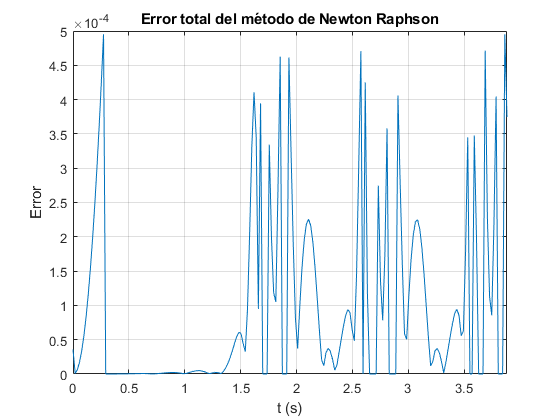



tiempo=Tabla_Cinematica.Tiempo;

figure()
plot(tiempo,error)
title("Error total del método de Newton Raphson")
xlabel("t (s)")
ylabel("Error")
grid on
xlim([0 tiempo(end)])


ExTiempo=TablaExcel.Tiempo;

Vmax=double(max(Tabla_Cinematica.Velocidad))*180/pi

Vmax = 370.8232

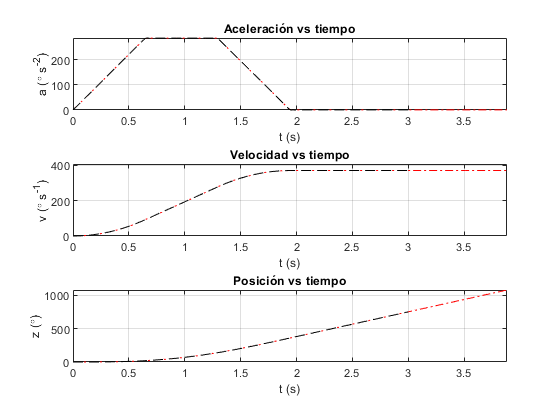

figure()
subplot(3,1,1)
plot(tiempo,Tabla_Cinematica.Aceleracion*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.A2*180/pi,"k--")
hold off
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (\circ s^{-2})')
xlim([0 tiempo(end)])

subplot(3,1,2)
plot(tiempo,Tabla_Cinematica.Velocidad*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.w2*180/pi,"k--")
hold off
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (\circ s^{-1})')
ylim([0 Vmax*1.1])
xlim([0 tiempo(end)])

subplot(3,1,3)
plot(tiempo,Tabla_Cinematica.Posicion*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.Theta2*180/pi,"k--")
hold off
title('Posición vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (\circ)')
xlim([0 tiempo(end)])

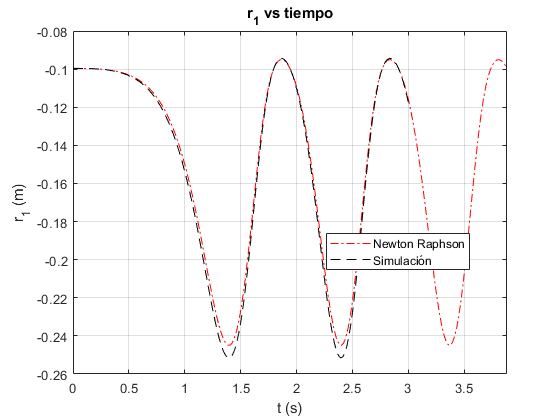


figure()
plot(tiempo,Tabla_Cinematica.R_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.R1-0.0257,"k--")
hold off
title("r_1 vs tiempo")
xlabel("t (s)")
ylabel("r_1 (m)")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación","Location","best")

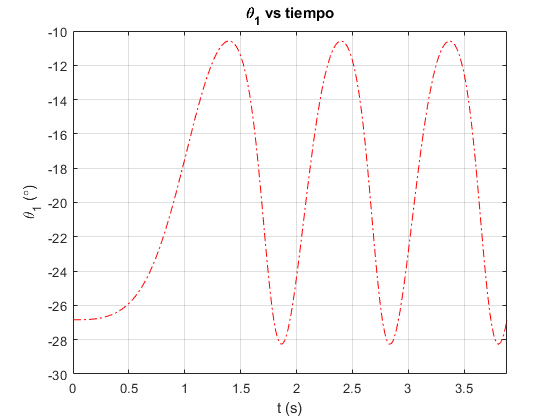


figure()
plot(tiempo,Tabla_Cinematica.theta_1*180/pi,"r-.")
title("\theta_1 vs tiempo")
xlabel("t (s)")
ylabel("\theta_1 (\circ)")
grid on
xlim([0 tiempo(end)])

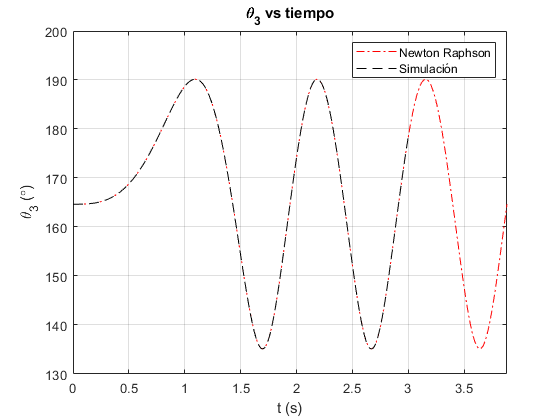


figure()
plot(tiempo,Tabla_Cinematica.theta_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.Theta3*180/pi,"k--")
hold off
title("\theta_3 vs tiempo")
xlabel("t (s)")
ylabel("\theta_3 (\circ)")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación")

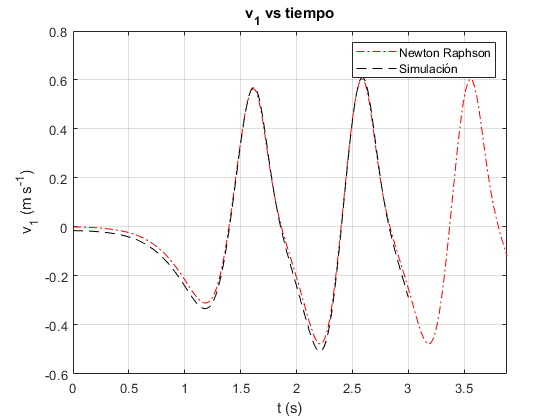



figure()
plot(tiempo,Tabla_Cinematica.V_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.Vr1,"k--")
hold off
title("v_1 vs tiempo")
xlabel("t (s)")
ylabel("v_1 (m s^{-1})")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación")

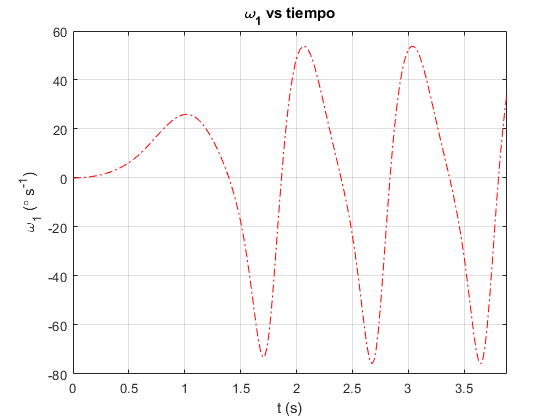


figure()
plot(tiempo,Tabla_Cinematica.omega_1*180/pi,"r-.")
title("\omega_1 vs tiempo")
xlabel("t (s)")
ylabel("\omega_1 (\circ s^{-1})")
grid on
xlim([0 tiempo(end)])

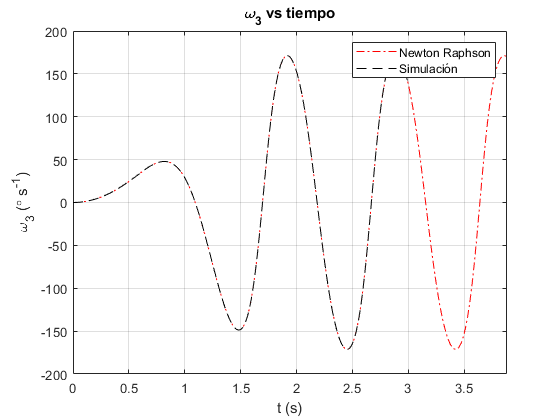


figure()
plot(tiempo,Tabla_Cinematica.omega_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.W3*180/pi,"k--")
hold off
title("\omega_3 vs tiempo")
xlabel("t (s)")
ylabel("\omega_3 (\circ s^{-1})")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación")

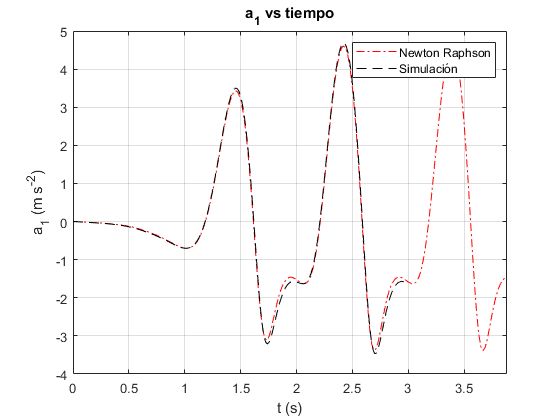


figure()
plot(tiempo,Tabla_Cinematica.a_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.Ar1,"k--")
hold off
title("a_1 vs tiempo")
xlabel("t (s)")
ylabel("a_1 (m s^{-2})")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación")

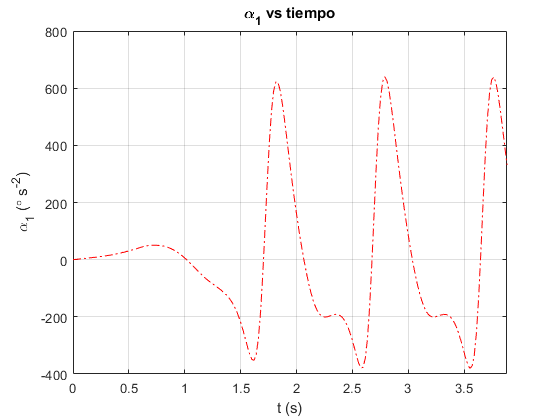


figure()
plot(tiempo,Tabla_Cinematica.alpha_1*180/pi,"r-.")
title("\alpha_1 vs tiempo")
xlabel("t (s)")
ylabel("\alpha_1 (\circ s^{-2})")
grid on
xlim([0 tiempo(end)])

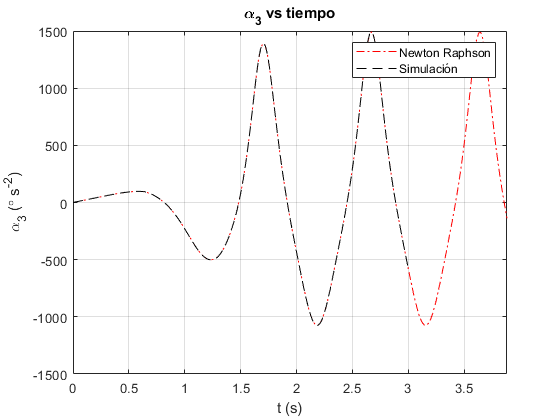


figure()
plot(tiempo,Tabla_Cinematica.alpha_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.A3*180/pi,"k--")
hold off
title("\alpha_3 vs tiempo")
xlabel("t (s)")
ylabel("\alpha_3 (\circ s^{-2})")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación")

function [Sol Error]= NR_Sistema(F,FJacInv,Pi,Ftheta_2,Fomega_2,Falpha_2)
syms omega_2 theta_2 alpha_2 
f=subs(F,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
JacInv=subs(FJacInv,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
p=Pi';
ValoresNR(1,:)=p';
iteraciones=50;
for i=1:iteraciones
    p=double(p-JacInv(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9))*f(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9)));
    ValoresNR(i+1,:)=double(p)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end
    Error=NormErrorNR(end);
    Sol=p';
end